     1



最终目标函数值为0.022567
最终迭代次数为200
最终目标函数值为1.0582


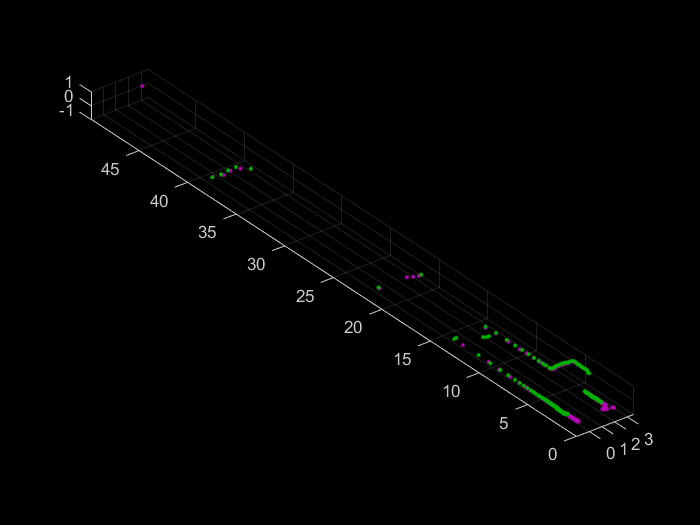

     2



最终目标函数值为0.35404
最终迭代次数为200
最终目标函数值为20.587


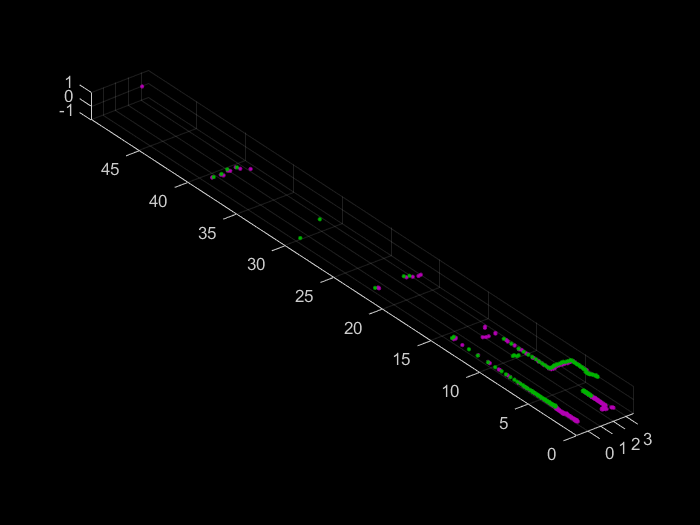

     3



最终目标函数值为0.052659
最终迭代次数为200
最终目标函数值为0.93906


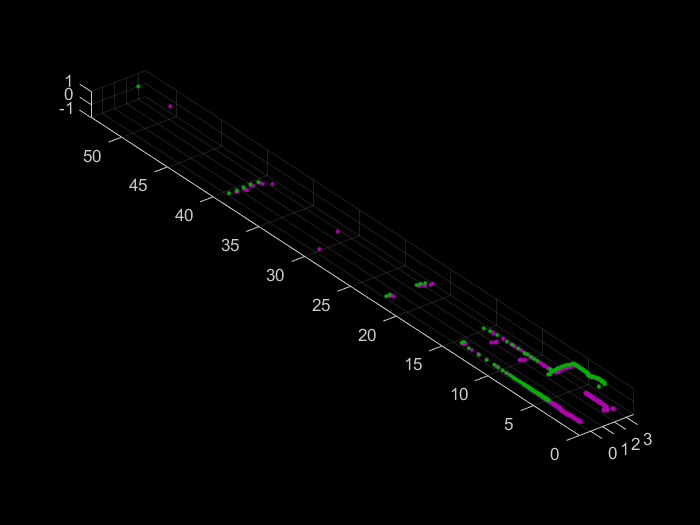

     4



最终目标函数值为0.031438
最终迭代次数为200
最终目标函数值为0.64017


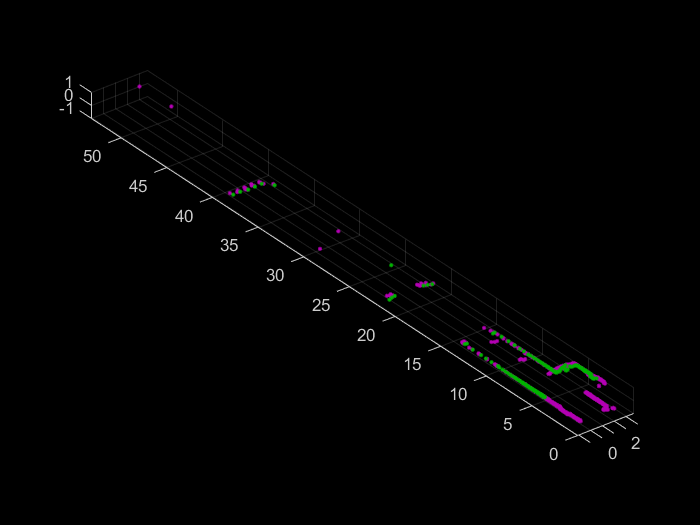

     5



最终目标函数值为0.030493
最终迭代次数为200
最终目标函数值为3.8881


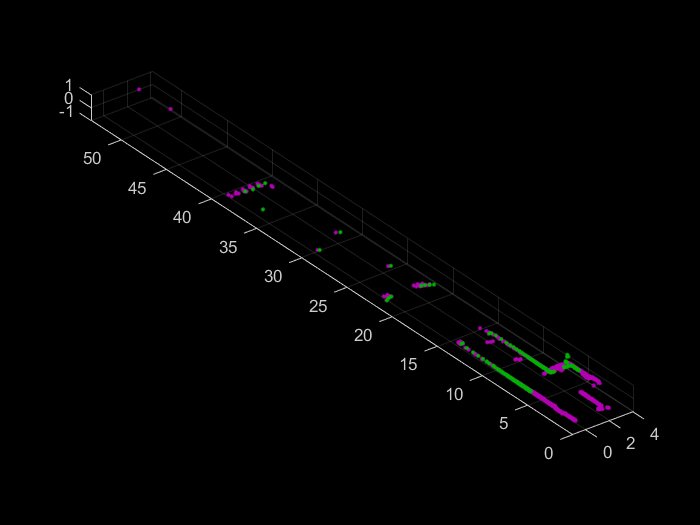

     6



最终目标函数值为0.0071579
最终迭代次数为200
最终目标函数值为0.7756


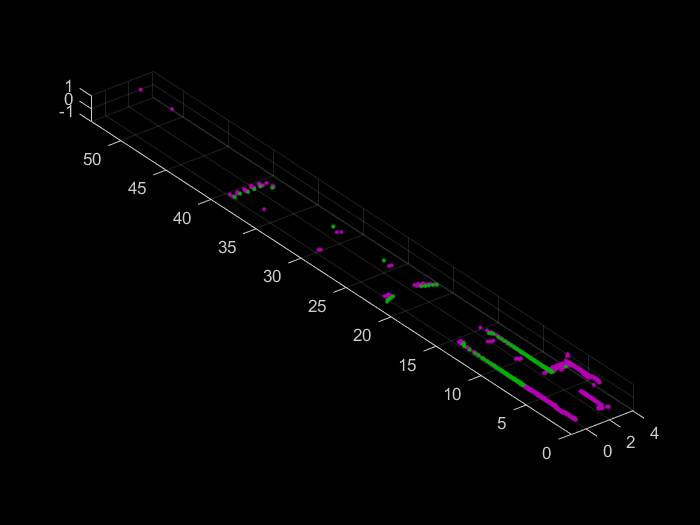

     7



最终目标函数值为0.073673
最终迭代次数为200
最终目标函数值为4.4805


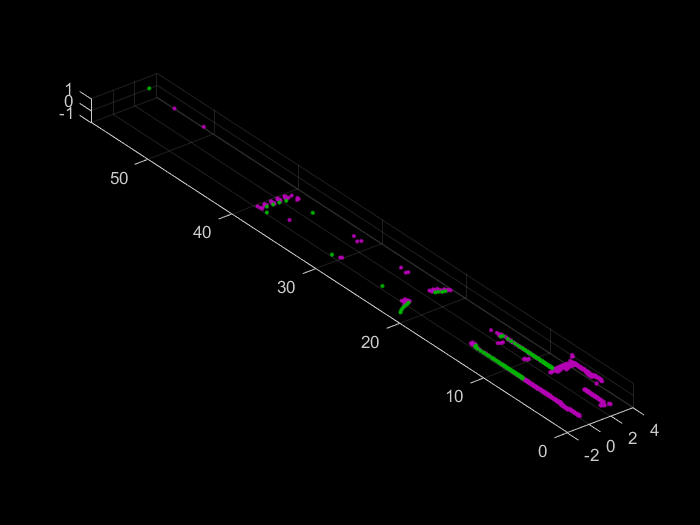

     8



最终目标函数值为0.013161
最终迭代次数为200
最终目标函数值为0.82502


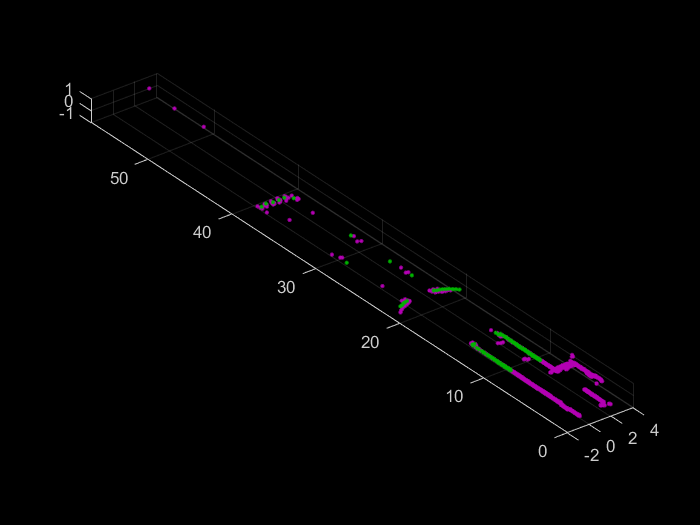

     9



最终目标函数值为0.038014
最终迭代次数为200
最终目标函数值为1.7016


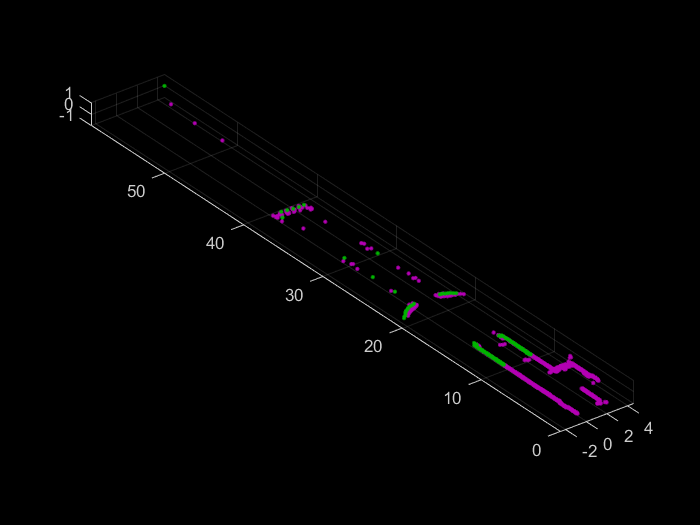

clear;clc;close all

laser_map = pcread('0.ply');

tform_init = affine3d([1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]);

robot_tf=cell(1,10);
robot_tf{1} = tform_init;

for i = 1:1:9
    
    disp(i);
    
    % read
    str = [num2str(i) , '.ply'];  
    curr_ply = pcread(str);
    
    % icp
    %[tform_init, curr_ply] = pcregistericp(curr_ply, laser_map, 'Metric','pointToPoint', 'InitialTransform', tform_init, 'MaxIterations', 100, 'Tolerance', [0.01, 0.001]);
    [tform_init, curr_ply] = myicp_ransac_plus(curr_ply, laser_map,"PointToLine","kdtree");
    %[tform_init,curr_ply] = my_ransac_icp(curr_ply, laser_map,"relative");

    robot_tf{i+1} = tform_init;
    figure;
    pcshowpair(laser_map, curr_ply, 'MarkerSize', 50);
    
    % merge
    laser_map = pcmerge(laser_map, curr_ply, 0.01);
    
end

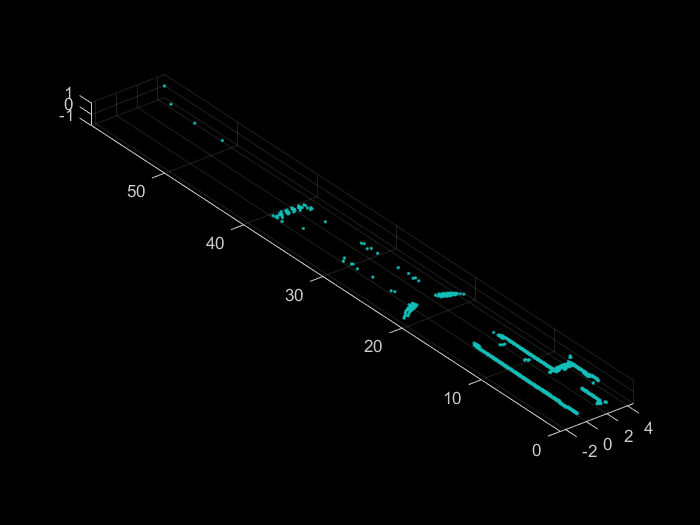


figure;
pcshow(laser_map, 'MarkerSize', 20);